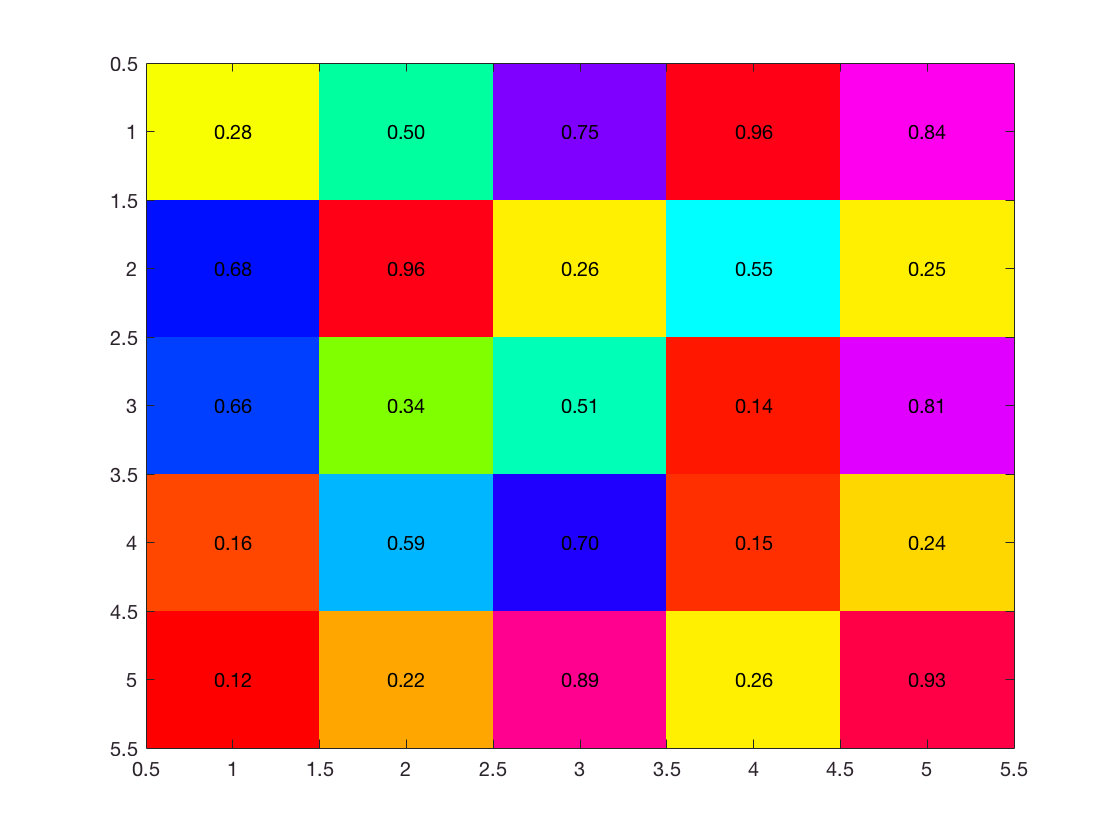

mat = rand(5);           %# A 5-by-5 matrix of random values from 0 to 1
imagesc(mat);            %# Create a colored plot of the matrix values
colormap(flipud('hsv'));  %# Change the colormap to gray (so higher values are
                         %#   black and lower values are white)

textStrings = num2str(mat(:),'%0.2f');  %# Create strings from the matrix values
textStrings = strtrim(cellstr(textStrings));  %# Remove any space padding
[x,y] = meshgrid(1:5);   %# Create x and y coordinates for the strings
hStrings = text(x(:),y(:),textStrings(:),...      %# Plot the strings
                'HorizontalAlignment','center');


midValue = length(colormap)/2  %# Get the middle value of the color range

midValue = 32

textColors = mat(:) > midValue,1,3;  %# Choose white or black for the

textColors = 25×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


ans = 1

                                             %#   text color of the strings so
                                             %#   they can be easily seen over
                                             %#   the background color
set(hStrings,{'Color'},num2cell(textColors,2));  %# Change the text colors

Error using matlab.graphics.primitive.Text/set
Error setting property 'Color' of class 'Text':
Color value must be a 3 element vector


set(gca,'XTick',1:5,...                         %# Change the axes tick marks
        'XTickLabel',{'A','B','C','D','E'},...  %#   and tick labels
        'YTick',1:5,...
        'YTickLabel',{'A','B','C','D','E'},...        
        'TickLength',[0 0]);